%f(x) = e^(-x)
%f'(x) = -e^(-x)
%f''(x) = e^(-x)
a = 0

a =      0


del = 0.1

del =    0.100000000000000


x_vec = -1:0.1:1;
pn_x = zeros(1,21);
f_x = exp(-x_vec);
error = 1;
answ = 100;
for n = 1:1:100
    for i = 1:1:21
        x = x_vec(i);
        pn_x(i) = exp(-a);
        for j = 1:1:n
            %pn_x(i)
            if mod(j, 2) == 0
                pn_x(i) = pn_x(i) + (power(x-a,j)/factorial(j))*(exp(-a));
            else
                pn_x(i) = pn_x(i) + (power(x-a,j)/factorial(j))*(-exp(-a));
            end
        end
    end
    error_arr = abs(pn_x-f_x);
    if(max(error_arr) < 1e-9)
        answ = n;
        break;
    end
    
end

answ

answ =     12


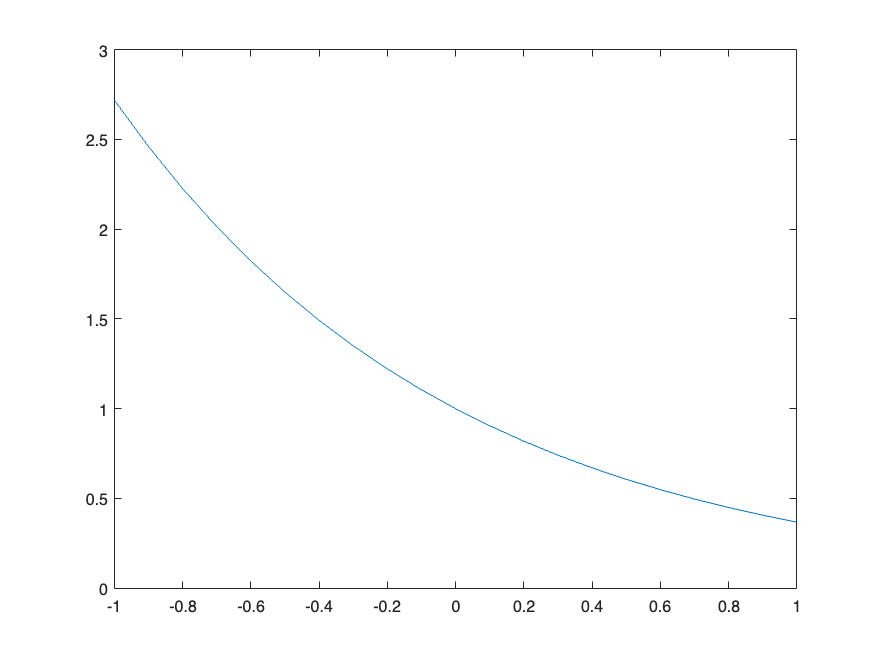

% pn_x
plot(x_vec, pn_x)

plot(x_vec, f_x)

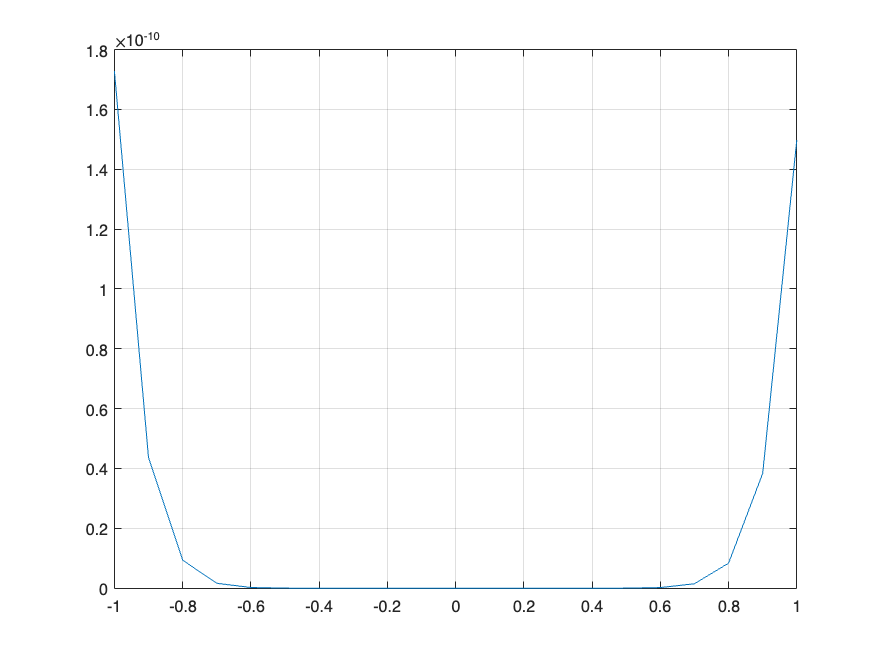

% error_arr = abs(pn_x-f_x)
plot(x_vec, error_arr)
grid ON;